此示例展示一个简单的数据筛选、PCA作图的流程。

首先载入UniExp数据库对象

DataSet=UniExp.DataSet(load(MATLAB.UITools.OpenFileDialog(Filter='UniExp数据库|*UniExp.mat',Title='选择UniExp数据库')));

错误使用 load
参数必须为文本标量。

预处理，每个步骤均为可选，根据实际情况单独运行

%按标拆分回合
DataSet.TagSplitTrial([-2 14]);
%重采样归一化，使得回合长度和采样率相同
DataSet.TrialSignals.TrialSignal=UniExp.SampleNormalize(DataSet.TrialSignals.TrialSignal);
%移除数据有问题的细胞
DataSet.RemoveCells([360,401,412,425,433,454,455,460,467,475,483,1063,1064]);
%为每个Block计算重复序数，即那个Block是那只鼠第几次做那个Design
DataSet.AddRepeatIndex;

这里假定重采样后所有数据采样率为8。如果不是，根据实际情况调整。

采样率单位/s，可根据DateTimes表中的SeriesInterval(㎳)求得。SampleRate=1000/SeriesInterval

SampleRate=8;

列出每条PCA线的筛选条件，可多选合并数据，留空表示该条件不做限制。其中：

RepeatIndex指示某种设计的会话的时间次序，如，BlueAudioWater会话的第1次。如果指定多个会话设计，将把这些会话取并集后再排序。也就是说，如果指定BlueAudioWater和AudioOnlyWater两种会话，但只指定了一个RepeatIndex为1，那么这两个会话只有时间上较早的那个会被选取。要将这两种会话的第一次实验都选取，必须指定这两种会话并集排序后的次序。

GroupIndex指示该条件的数据将被归入哪条线。例如，如果有两行条件被归入同一条线，这意味着数据将被这两行条件各自选取得到两个部分数据，然后将所有的回合累积后归入这条线。GroupIndex指定的线条编号必须是连续的正整数，可以有重复但不能有遗漏。例如最大的线条编号如果是5，那么1~4都必须至少出现一次，这样将绘制5条线。如果要删除1号线，必须将2~5各自减1。

建议使用Tab缩进制表，提高可读性

QueryTable=cell2table({
	%Design									RepeatIndex		Stimulus		GroupIndex		Mouse					ZLayer
	["BlueOnlyWater","BlueAudioWater"]		1				"BlueOnly"		1				["0030","vtf0045"]		"L2"
	["BlueOnlyWater","BlueAudioWater"]		2				"BlueOnly"		2				["0030","vtf0045"]		"L2"
	["BlueOnlyWater","BlueAudioWater"]		2				"BlueWater"		3				["0030","vtf0045"]		"L2"
	"AudioOnlyWater"						1				"AudioOnly"		4				"0030"					"L2"
	"BlueAudioWater"						2				"AudioOnly"		4				"vtf0045"				"L2"
	"AudioOnlyWater"						1				"AudioWater"	5				"0030"					"L2"
	"BlueAudioWater"						2				"AudioWater"	5				"vtf0045"				"L2"
	"AudioOnlyWater"						2				"AudioOnly"		6				"0030"					"L2"
	"BlueAudioWater"						3				"AudioOnly"		6				"vtf0045"				"L2"
	"AudioOnlyWater"						2				"AudioWater"	7				"0030"					"L2"
	"BlueAudioWater"						3				"AudioWater"	7				"vtf0045"				"L2"
},VariableNames=[ ...
	"Design"								"RepeatIndex"	"Stimulus"		"GroupIndex"	"Mouse"					"ZLayer" ...
	]);
%其它参数详见LinearPca文档
[PcaLines,Explained,Coeff,CellUID]=DataSet.LinearPca(QueryTable,UniExp.Flags.log2FdF0,1:SampleRate*2,NumComponents=3,AccumulateMethod=UniExp.Flags.Median);

Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to the parallel pool (number of workers: 3).


PcaLines是元胞列向量，每个元胞对应QueryTable里的GroupIndex序数。元胞内是数值矩阵，表示线上按时间顺序的每个点的主成分分数，第1维是时间，第2维是主成分。后续可以据此作图。

作图。首先生成优化的颜色配置：

Colors=GlobalOptimization.ColorAllocate(numel(PcaLines),[1 1 1]);

GlobalSearch stopped because it analyzed all the trial points.

All 98 local solver runs converged with a positive local solver exit flag.


Colors =     1.0000    0.0000    1.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    0.0000


图例文本：

LegendText=[
	"Light-only naive"
	"Light-only learned"
	"Light-water learned"
	"Audio-only"
	"Audio-water transfer"
	"Audio-only leanred"
	"Audio-water learned"
	"0s"
	"1s"
	"3s"
];

关键时点突出显示：

KeyIndex=[2,3,5]*SampleRate+1;

关键时点符号

KeyMarkers='o^s';

作图

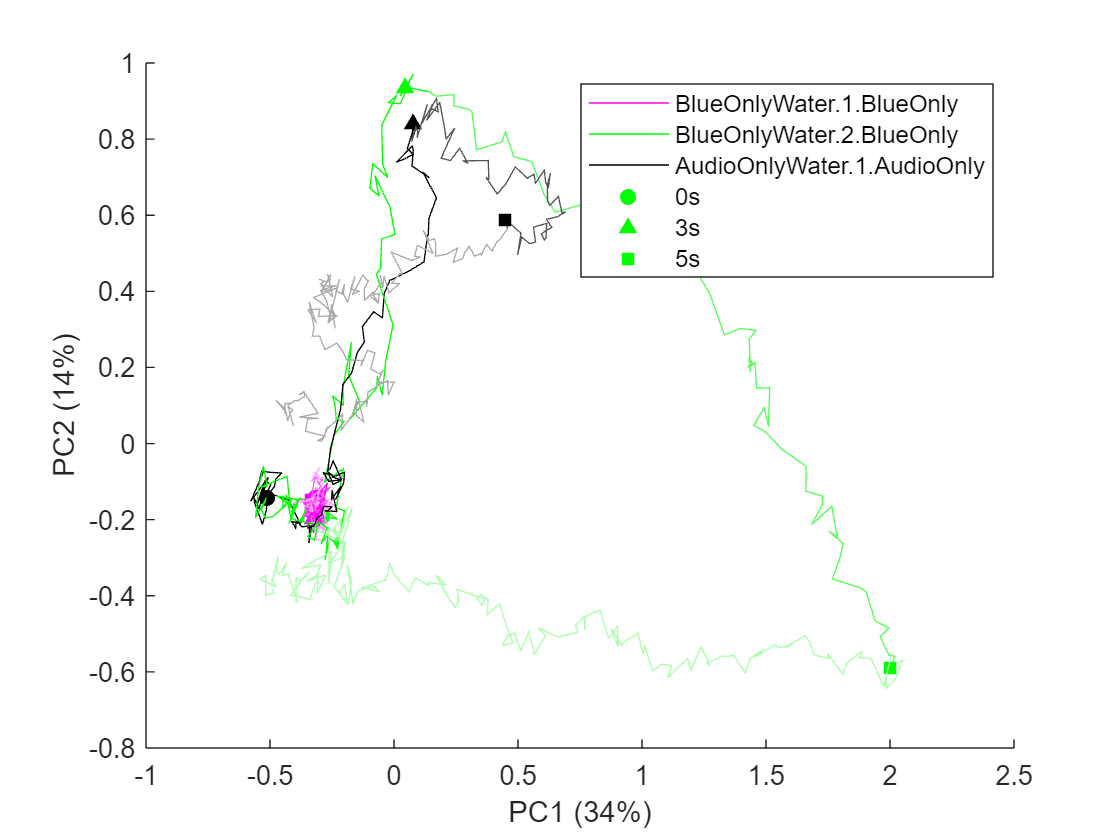

figure;
[Lines,Scatters]=UniExp.SegmentFadePlot(permute(cat(3,PcaLines{:}),[1,3,2]),Colors,KeyIndex,KeyMarkers);
legend(vertcat(Lines,Scatters),LegendText);
xlabel(sprintf('PC1 (%.2g%%)',Explained(1)));
ylabel(sprintf('PC2 (%.2g%%)',Explained(2)));
zlabel(sprintf('PC3 (%.2g%%)',Explained(3)));

调好角度以后保存

Fig=gcf;
Fig.Renderer='painters';
saveas(Fig,'矢量图.svg');